# IMU Analysis

clear
[timestamps, timedelta, data] = parseDataSet("DataSets/cl_zn_step.csv");

% Extract data columns
ax = data(:, 3); 
ay = data(:, 4); 
az = data(:, 5);
leftspeed = data(:, 9); 
leftvolt = data(:, 10);

% Compute pitch estimate
pitch = rad2deg(atan2(-ax, az));

gx = data(:,6);
gy = data(:,7);
gz = data(:,8);

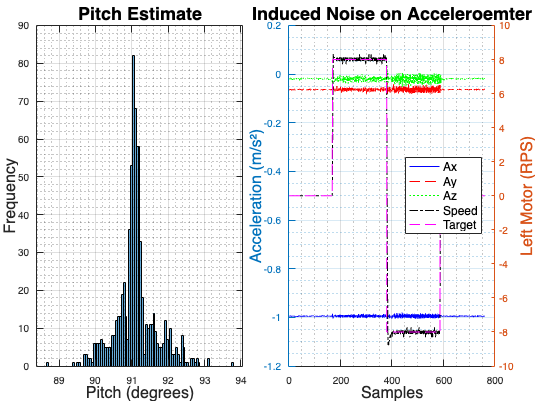


% Create tiled layout
figure;
tiledlayout(1,2, "TileSpacing","tight", "Padding","tight");

% Histogram of Pitch Values
nexttile;
histogram(pitch, 100);

title("Pitch Estimate", 'FontSize', 18);
ylabel("Frequency", 'FontSize', 16);
xlabel("Pitch (degrees)", 'FontSize', 16);
grid on; grid minor;

%Accelerometer and Left Motor Data
nexttile;
yyaxis left;
plot(ax, 'b'); hold on; 
plot(ay, 'r'); 
plot(az, 'g'); 
ylabel('Acceleration (m/s²)', 'FontSize',16);
yyaxis right;
plot(leftspeed, 'k-.'); 
plot(leftvolt, 'm--'); 
ylabel('Left Motor (RPS)','FontSize',16);
title("Induced Noise on Acceleroemter",  'FontSize', 18);
xlabel("Samples", 'FontSize', 16);
legend("Ax", "Ay", "Az", "Speed", "Target", 'Location', 'best', 'FontSize', 12);
grid on; grid minor;